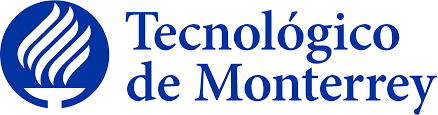

## Implementación de robótica inteligente (TE3002B)

## Actividad 1.9 (Landmarks)

### Pamela Hernández Montero A01736368

**Indicaciones:**

Generar los waypoints (puntos de referencia) necesarios para obtener las siguientes trayectorias, ajustando el tiempo de muestreo: “sampleTime”, vector de tiempo: “tVec”, pose inicial: “initPose”, y los waypoints: “waypoints”.

Antes que nada, dibujé las coordenadas de las figuras para facilitarme determinar los waypoints a pasar.

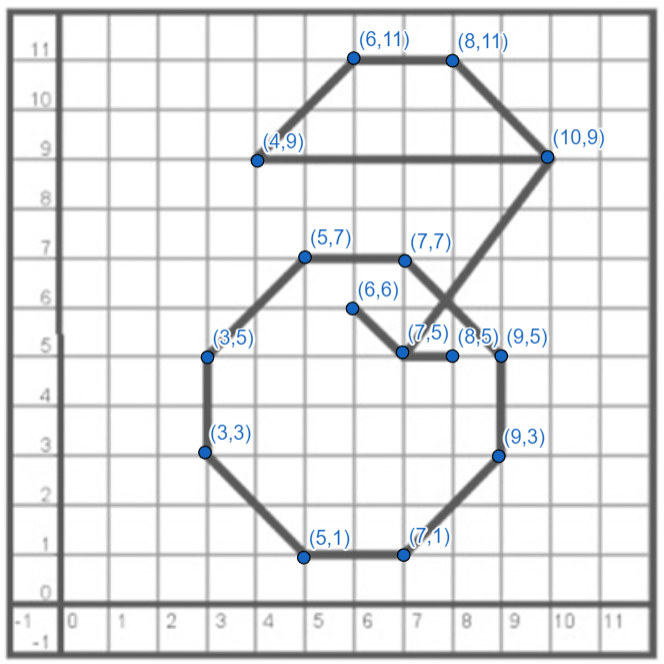

Primero empecé por la figura con menos puntos, en este caso, la cereza. Para ello, busqué un punto de origen que fuera el mejor para trazar una trayectoria corta y evitar pasar por los mismos puntos muchas veces. En este caso, el origen de mi trayectoria es en (8,5). Por otro lado, determiné una orientación que evitara la rotación del carrito al empezar la simulación; en este caso, pi.

Para todas las figuras cambié los valores de DesiredLinearVelocity a 0.5 y MaxAngularVelocity a 50, para que las curvas fueran más rápidas y no tan largas como en la parte 1.

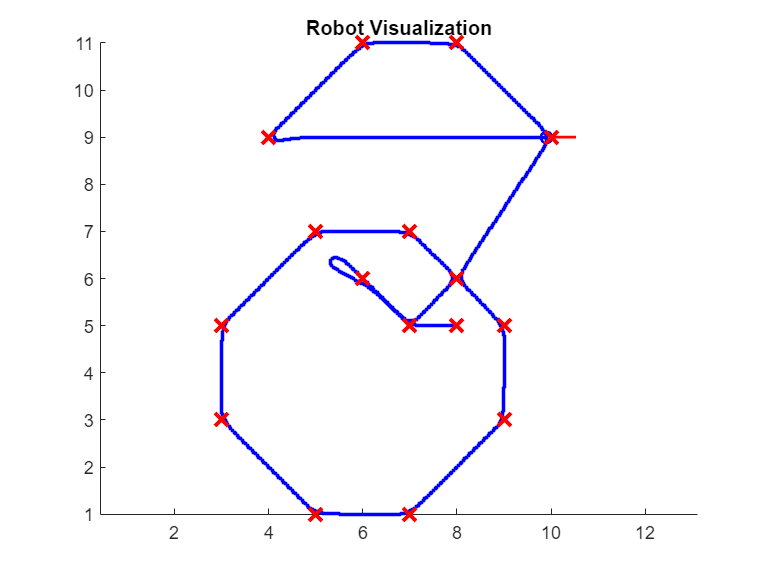

%% Define Vehicle
R = 0.02;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:85 ;      % Time array

initPose = [8;5; pi];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [8,5; 7,5; 6,6; 7,5; 8,6; 7,7; 5,7; 3,5; 3,3; 5,1; 7,1; 9,3; 9,5; 8,6; 10,9; 8,11; 6,11; 4,9; 10,9];

% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity = 50;
%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

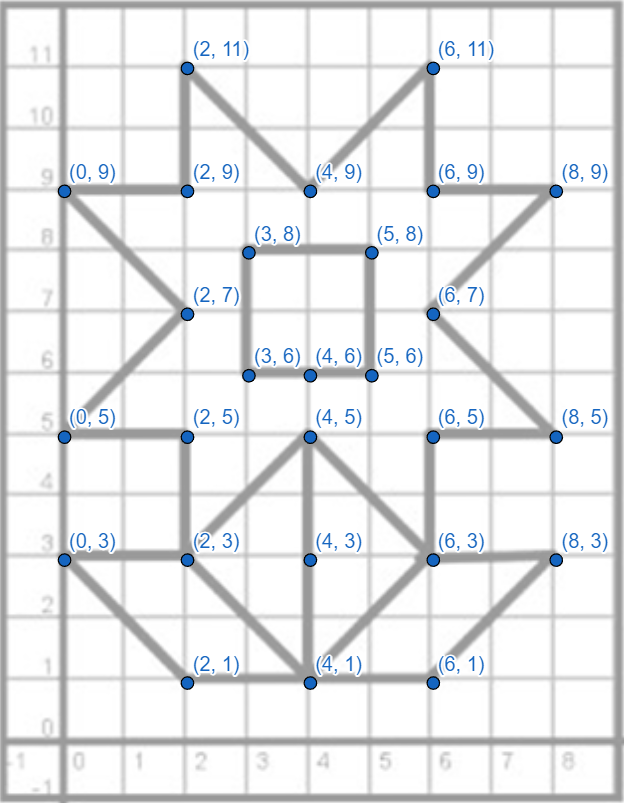

Para la segunda figura únicamente cambié los valores de los waypoints, ajustándolos a la mejor trayectoria, y modifiqué el valor final de tVec. Del mismo modo, configuré initPose para que el origen en X y Y, así como la orientación del carrito, se acoplaran en dirección al segundo punto de los waypoints.

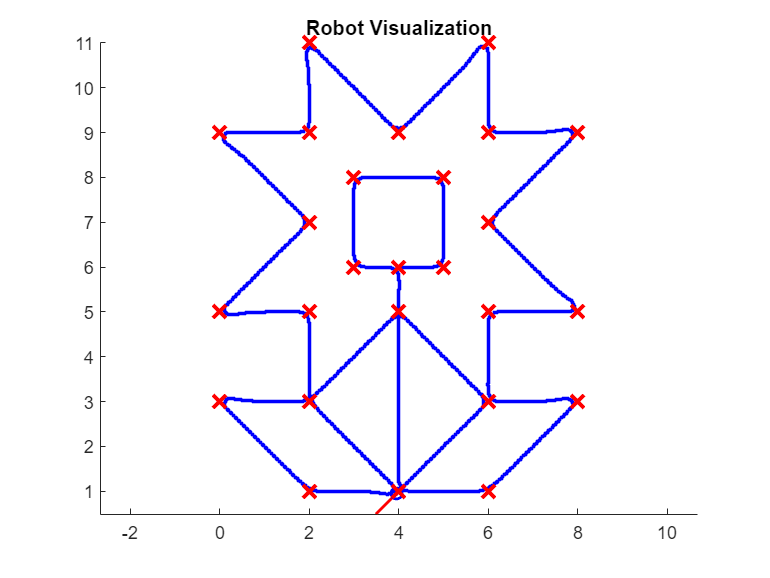

%% Define Vehicle
R = 0.02;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);
%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:135.8;       % Time array

initPose = [4;6; 2*pi];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints = [4,6;5,6; 5,8; 3,8; 3,6; 4,6; 4,5; 4,1;6,1;8,3;6,3; 
    6,5; 8,5; 6,7; 8,9; 6,9; 6,11; 4,9; 2,11; 2,9; 0,9; 
    2,7; 0,5; 2,5;2,3;4,1;2,1;0,3;2,3;4,5;6,3;4,1];
%waypoints = 
% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity = 50;
%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef); 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
    
end

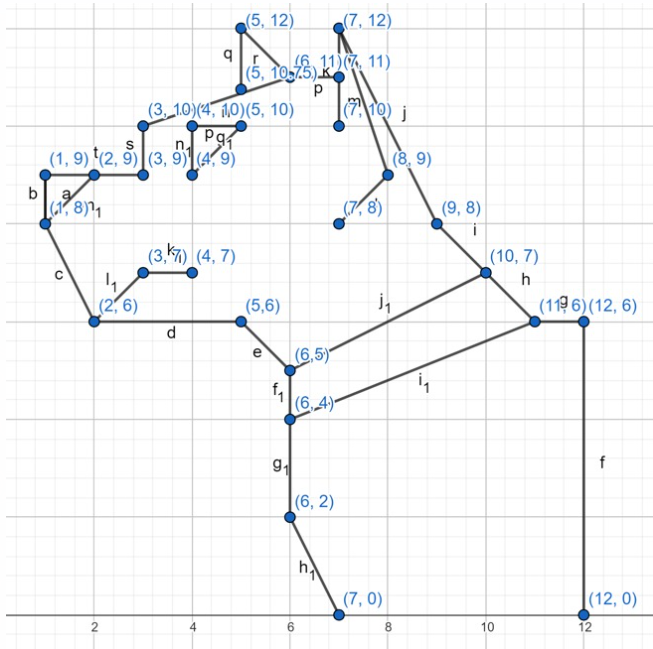

Por último, la figura final fue la más compleja debido a la cantidad de puntos dentro de los waypoints. Modifiqué el valor de tVec de manera óptima y ajusté initPose estratégicamente para lograr la mejor adaptación a los puntos. En general, su configuración fue fácil de adaptar gracias a la experiencia adquirida con las figuras anteriores.

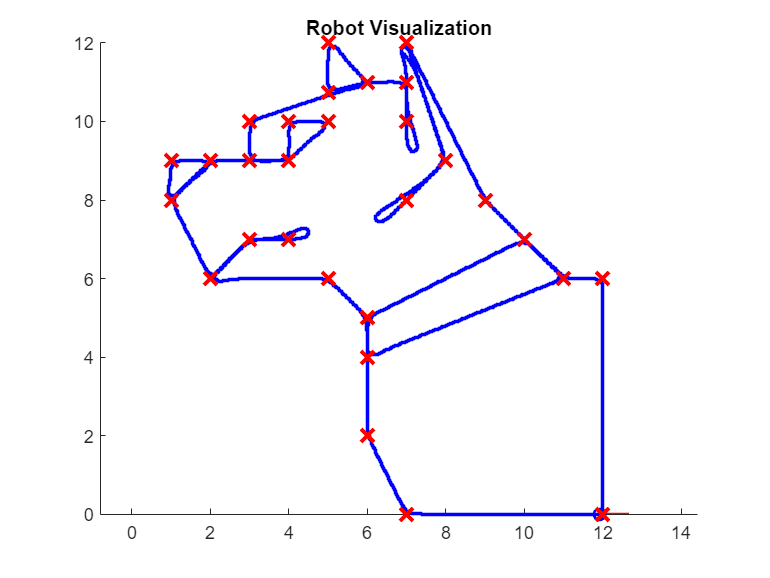

%% Define Vehicle
R = 0.02;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);
%% Simulation parameters
sampleTime = 0.1;               % Sample time [s]
tVec = 0:sampleTime:165;       % Time array

initPose = [12;0; pi/2];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
waypoints =[12,0; 12,6; 11,6; 10,7; 9,8; 7,12; 8,9; 7,8; 8,9; 7,12; 7,11; 7,10; 7,11; 6,11; 5,10.75; 5,12; 6,11; 3,10; 3,9; 4,9; 4,10; 5,10; 4,9; 2,9; 1,8; 1,9; 2,9; 1,8; 2,6; 3,7; 4,7; 3,7; 2,6; 5,6; 6,5; 6,4; 11,6; 10,7; 6,5; 6,2; 7,0; 12,0];
%waypoints = 
% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;
%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.35;
controller.DesiredLinearVelocity = 0.5;
controller.MaxAngularVelocity = 50;
%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints);
    waitfor(r);
    
end

**Conclusión:**

Este trabajo fue fácil de desarrollar pero laborioso debido a la necesidad de encontrar la mejor trayectoria que siguiera los puntos de la figura. En general, se trató de un proceso de prueba y error que demandó tiempo y atención meticulosa. Cada parte de esta actividad ayudo a comprender la importancia de la planificación cuidadosa y la optimización en la ejecución de tareas robóticas